% -------------------------------------------------------------------------
% BLE PPG SIGNAL ACQUISITION AND ANALYSIS SCRIPT
% -----------------------------------------------------------------------------------------
% This script acquires photoplethysmographic (PPG) signals (IR and Red) 
% and temperature data via BLE for a fixed duration. 
% It performs the following:
% - Extracts (via heartbeat_BLE MATLAB function)
%   and plots time-aligned IR and Red signals
% - Computes and visualizes temperature trends
% - Calculates Power Spectral Density (PSD) for both signals
% - Estimates Signal-to-Noise Ratio (SNR) within the heart rate frequency band (40–180 bpm)
% - Saves the workspace to a .mat file with user-defined name and overwrite protection
% -----------------------------------------------------------------------------------------
% NOTE: To change the save destination, manually update the 'fixedPath' variable.
% -----------------------------------------------------------------------------------------

clearvars;
clc;

global dataArray dataIndex fricezione tempdata tempIndex;

% --- Acquisition duration in seconds ---
duration = 60;

% --- Start BLE data acquisition for the specified duration ---
heartbeat_BLE(duration); 

Connessione al dispositivo BLE "AA Pulse Oximeter"...
Dispositivo connesso!
Notifiche BLE abilitate.
Lettura per 60 secondi...
Acquisizione terminata.
Attendo ricezione asincrona temperatura (via callback)...
Totale campioni ricevuti: 5820
Frequenza media: 96.95 Hz
Totale temperature ricevute: 59


% --- Extract time and signals, excluding empty entries due to incomplete acquisition rate < 100 Hz ---

t_raw = dataArray(1:dataIndex-1, 1) / 1e6; % raw timestamp in seconds
t = t_raw - t_raw(1);  % time aligned to start at 0
fprintf('Start t = %.2f s, End t = %.2f s, Duration = %.2f s\n', ...
         t(1), t(end), t(end) - t(1));

Inizio t = 0.00 s, Fine t = 60.03 s, Durata = 60.03 s


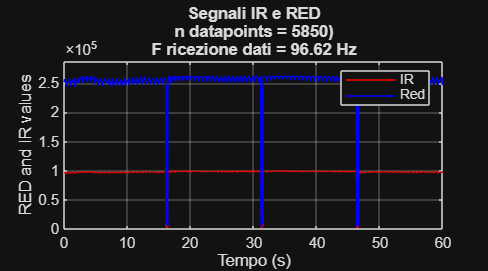

% --- Extract IR and Red signals ---

ir = dataArray(1:dataIndex-1, 2);       % IR signal
red = dataArray(1:dataIndex-1, 3);      % Red signal

% --- Extract temperature data, excluding eventual initial zero values ---

valid_idx = tempdata(:,2) ~= 0;
temp_times_raw = tempdata(valid_idx, 1) / 1e3;
temp_vals = tempdata(valid_idx, 2);

% time aligned to start at 0
temp_times = temp_times_raw - temp_times_raw(1);

fs = fricezione; % sampling frequency in Hz 

%% --- Plot IR and Red signals over time ---
figSignals = figure('Name','Segnali IR e Red', 'Position', [100 100 900 500]);

% label with additional info
labelDP = sprintf('n datapoints = %d)', length(t));
labelFS = sprintf('F data reception = %.2f Hz', fs);

plot(t, ir, 'r', 'DisplayName','IR'); hold on;
plot(t, red, 'b', 'DisplayName','Red');

xlabel('Time (s)');
ylabel('RED and IR values');
legend('show');
title(sprintf('IR and RED signals \n%s\n%s', labelDP, labelFS));
grid on;
xlim([0 duration]);
signal_max = max([max(ir), max(red)]);
margin = 0.1 * signal_max;  % 10% margin above the maximum
ylim([0, signal_max + margin]);

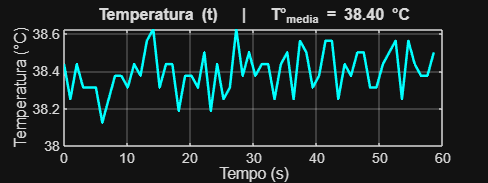

% --- Plot temperature data ---

% Calculate average temperature 
mean_temp = mean(temp_vals);            

% Temperature figure
figTemp = figure('Name','Temperature', 'Position', [100 550 800 300]);
plot(temp_times, temp_vals, 'c-', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Temperature (°C)');
title(sprintf('Temperature (t)   |   T°_{mean} = %.2f °C', mean_temp));
grid on;
xlim([0 duration]);  

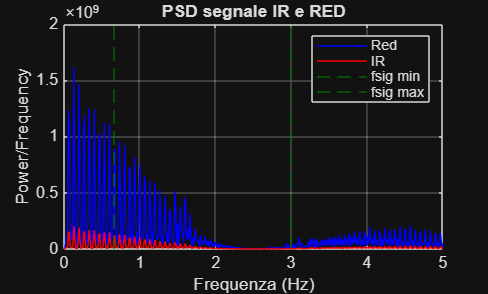

% --- Define frequency band of interest (40–180 bpm) ---

bpm_low = 40;          % low bpm boundary
bpm_high = 180;        % high bpm boundary
f_low = bpm_low / 60;  % convert bpm in Hz 
f_high = bpm_high / 60;

% --- Center signals around zero for PSD analysis ---
ir = ir - mean(ir);
red = red - mean(red);

% --- Compute Power Spectral Density (PSD) using periodogram ---
[pxx_red, f_red] = periodogram(red, [], [], fs);
[pxx_ir, f_ir]   = periodogram(ir, [], [], fs);

% --- Plot PSDs for IR and Red signals ---
figPSD = figure('Name','PSD IR e Red');
plot(f_red, pxx_red, 'b', 'DisplayName','Red'); hold on;
plot(f_ir, pxx_ir, 'r', 'DisplayName','IR');
h1 = xline(f_low, '--', 'Color', [0 0.5 0], 'DisplayName', 'fsig min'); 
h2 = xline(f_high, '--', 'Color', [0 0.5 0], 'DisplayName', 'fsig max');

h1.Label = '';
h2.Label = '';
xlabel('Frequen (cyHz)');
ylabel('Power/Frequency');
legend('show');
title('PSD IR and RED signals');
xlim([0 5]);  % focus on heart rate frequency band
grid on;


% --- Compute power inside and outside the heart rate band ---
freq_mask_red = (f_red >= f_low) & (f_red <= f_high);
freq_mask_ir  = (f_ir  >= f_low) & (f_ir  <= f_high);

power_red_inband  = trapz(f_red(freq_mask_red), pxx_red(freq_mask_red));
power_red_outband = trapz(f_red(~freq_mask_red), pxx_red(~freq_mask_red));

power_ir_inband  = trapz(f_ir(freq_mask_ir), pxx_ir(freq_mask_ir));
power_ir_outband = trapz(f_ir(~freq_mask_ir), pxx_ir(~freq_mask_ir));

% --- Compute Signal-to-Noise Ratio (SNR) as in-band / out-of-band power ---
SNR_red = power_red_inband / power_red_outband;
SNR_ir = power_ir_inband / power_ir_outband;

% --- Convert SNR to decibels ---
SNR_red_dB = 10 * log10(SNR_red);
SNR_ir_dB = 10 * log10(SNR_ir);

% --- Display SNR results ---
fprintf('Red Signal:\n');

Red Signal:


fprintf('Power in band (40-180 bpm): %.4f\n', power_red_inband);

Power in band (40-180 bpm): 232535206.1577


fprintf('Power out of band: %.4f\n', power_red_outband);

Power out of band: 1636239142.5983


fprintf('SNR: %.4f\n\n', SNR_red);

SNR: 0.1421




fprintf('IR Signal:\n');

IR Signal:


fprintf('Power in band (40-180 bpm): %.4f\n', power_ir_inband);

Power in band (40-180 bpm): 32496283.1145


fprintf('Power out of band: %.4f\n', power_ir_outband);

Power out of band: 228353342.2341


fprintf('SNR: %.4f\n', SNR_ir);

SNR: 0.1423



%% --- Save workspace to .mat file ---
fixedPath = 'C:\Users\ginev\Desktop\matlab\arduino\data\50mA';

% --- Prompt user for file name ---
fileName = input('Enter the name of the file (without extension): ', 's');

if isempty(fileName)
    disp('Invalid file name. Saving cancelled.');
else
    fullname = fullfile(fixedPath, [fileName, '.mat']);
    
    if exist(fullname, 'file') == 2

        % --- File exists: ask for overwrite confirmation ---
        answer = input(sprintf('The file "%s" already exists. Do you want to overwrite it? (s/n): ', fileName), 's');
        if strcmpi(answer, 's')
            save(fullname);
            fprintf('Workspace saved in: %s\n', fullname);
        else
            disp('Saving cancelled by the user.');
        end
    else

        % --- File does not exist: save directly ---
        save(fullname);
        fprintf('Workspace saved in: %s\n', fullname);
    end
 end

Workspace salvato in: C:\Users\ginev\Desktop\matlab\arduino\data\50mA\4.mat
